# Microarray Data Analysis

In this tutorial, we will analyze microarray data available from GEO repository hosted at NCBI ([http://www.ncbi.nlm.nih.gov/geo/](http://www.ncbi.nlm.nih.gov/geo/)). We will rely on Matlab's Bioinformatics Toolbox for some of the file parsing and data analysis functionality.

We'll analyze the experimental data that was used in the following study: "A stromal gene signature associated with inflammatory breast cancer.", Boersma et.al., 2008. [https://www.ncbi.nlm.nih.gov/pubmed/17999412](https://www.ncbi.nlm.nih.gov/pubmed/17999412)

**Abstract:** The factors that determine whether a breast carcinoma will develop into inflammatory breast cancer (IBC) remain poorly understood. Recent evidence indicates that the tumor stroma influences cancer phenotypes. We tested the hypotheses that the gene expression signature of the tumor stroma is a distinctive feature of IBC. We used laser capture microdissection to obtain enriched populations of tumor epithelial cells and adjacent stromal cells from 15 patients with IBC and 35 patients with invasive, noninflammatory breast cancer (non-IBC). Their mRNA expression profiles were assessed using Affymetrix GeneChips. In addition, a previously established classifier for IBC was evaluated for the resulting data sets. The gene expression profile of the tumor stroma distinguished IBC from non-IBC, and a previously established IBC prediction signature performed better in classifying IBC using the gene expression profile of the tumor stroma than it did using the profile of the tumor epithelium. In a pathway analysis, the genes differentially expressed between IBC and non-IBC tumors clustered in distinct pathways. We identified multiple pathways related to the endoplasmic stress response that could be functionally significant in IBC. Our findings suggest that the gene expression in the tumor stroma may play a role in determining the IBC phenotype.

The data is available at [https://www.ncbi.nlm.nih.gov/geo/query/acc.cgi?acc=GSE5847](https://www.ncbi.nlm.nih.gov/geo/query/acc.cgi?acc=GSE5847)

## GEO data types

- GSM: An individual microarray Sample (e.g., patient, or tissue).

- GSE: A Series, representiing an experimental study. A GSE contains one or more GSM entries.

- GPL: Platform data, containing information about microarray probes. Each GSM sample is associated with a GPL. E.g., to find out the gene symbols for a GSM, you would need to consult with the GPL used in that study.

## Variable names and terms

- gse: The struct returned from Matlab's geoseriesread(). Contains all the information contained in a GSE.

- d: The DataMatrix object representing the GSE data. We'll also use the prefix d to denote other DataMatrix objects, e.g., dpvals.

- m: A numerical matrix (e.g., converting d into a double).

- MAP_GSE_GPL: used to map gse probes to gpl indices, so we can get e.g., gene symbol information for a probe. IBC: inflammatory breast cancer Epithelial: the type of cells forming the breast cancer Stroma: fatty tissue (adipocytes) and fibroblasts

if true

## Download GSE file and use Matlab's geoseriesread() to parse it.

[https://www.ncbi.nlm.nih.gov/geo/query/acc.cgi?acc=GSE5847](https://www.ncbi.nlm.nih.gov/geo/query/acc.cgi?acc=GSE5847) See the bmes_downloadandparsegse() function for details.

gse=bmes_downloadandparsegse('GSE5847')

Reading C:\Users\kabil\AppData\Local\Temp\GSE5847.txt ...


gse = struct with fields:
    Header: [1×1 struct]
      Data: [22283×95 bioma.data.DataMatrix]


% gse.Data is a DataMatrix object, similar to a Matlab table. In addition
% to the numerical matrix, it internally stores the row & column names.
get(gse.Data)

            Name: ''
        RowNames: {22283×1 cell}
        ColNames: {1×95 cell}
           NRows: 22283
           NCols: 95
           NDims: 2
    ElementClass: 'double'



d = gse.Data; %Let's use d for short, because we'll use this often.

Print first 6 Probes and first 5 samples

d(1:6,1:5)

ans = 
                 GSM136326    GSM136327    GSM136328    GSM136329    GSM136330
    1007_s_at     10.45       9.3995       9.4248       9.4729       9.2788   
    1053_at      5.7195       4.8493       4.7321       4.7289       5.3264   
    117_at       5.9387       6.0833        6.448       6.1769       6.5446   
    121_at       8.0231       7.8947        8.345       8.1632       8.2338   
    1255_g_at    3.9548       3.9632       3.9641       4.0878       3.9989   
    1294_at       7.909        8.364       8.2719       8.3582          7.7   


## GSE Header information

gse.Header

ans = struct with fields:
     Series: [1×1 struct]
    Samples: [1×1 struct]


gse.Header.Series

ans = struct with fields:
                         title: 'Tumor and stroma from breast by LCM'
                 geo_accession: 'GSE5847'
                        status: 'Public on Sep 30 2007'
               submission_date: 'Sep 15 2006'
              last_update_date: 'Mar 18 2020'
                     pubmed_id: '17999412↵19225562↵20978357'
                       summary: 'Tumor epithelium and surrounding stromal cells were isolated using laser capture microdissection of human breast cancer to examine differences in gene expression based on tissue types from inflammatory and non-inflammatory breast cancer↵Keywords: LCM'
                overall_design: 'We applied LCM to obtain samples enriched in tumor epithelium and stroma from 15 IBC and 35 non-IBC cases to study the relative contribution of each component to the IBC phenotype and to patient survival. '
                          type: 'Expression profiling by array'
                   contributor: 'Stefan,,Ambs↵Brenda,,Boersma↵Ma

Get the title of the first sample

gse.Header.Samples.title{1}

ans = 'LCM stroma sample from patient #37'

Print all of the available characteristics of the 20th sample

gse.Header.Samples.characteristics_ch1(:,20)

ans = 7×1 cell array
    {'diagnosis: non-IBC'     }
    {'status: Alive'          }
    {'patient_id: 8'          }
    {'race: European American'}
    {'tnm_stage: IIA'         }
    {'er_status: POS'         }
    {'tissue: Stroma'         }

Print the diagnostic information of all samples

disp(gse.Header.Samples.characteristics_ch1(1,:)')

    {'diagnosis: IBC'    }
    {'diagnosis: IBC'    }
    {'diagnosis: IBC'    }
    {'diagnosis: IBC'    }
    {'diagnosis: IBC'    }
    {'diagnosis: IBC'    }
    {'diagnosis: IBC'    }
    {'diagnosis: IBC'    }
    {'diagnosis: IBC'    }
    {'diagnosis: IBC'    }
    {'diagnosis: IBC'    }
    {'diagnosis: IBC'    }
    {'diagnosis: IBC'    }
    {'diagnosis: non-IBC'}
    {'diagnosis: non-IBC'}
    {'diagnosis: non-IBC'}
    {'diagnosis: non-IBC'}
    {'diagnosis: non-IBC'}
    {'diagnosis: non-IBC'}
    {'diagnosis: non-IBC'}
    {'diagnosis: non-IBC'}
    {'diagnosis: non-IBC'}
    {'diagnosis: non-IBC'}
    {'diagnosis: non-IBC'}
    {'diagnosis: non-IBC'}
    {'diagnosis: non-IBC'}
    {'diagnosis: non-IBC'}
    {'diagnosis: non-IBC'}
    {'diagnosis: non-IBC'}
    {'diagnosis: non-IBC'}
    {'diagnosis: non-IBC'}
    {'diagnosis: non-IBC'}
    {'diagnosis: non-IBC'}
    {'diagnosis: non-IBC'}
    {'diagnosis: non-IBC'}
    {'diagnosis: non-IBC'}
    {'diagnosis: non-IBC'}
 

## GPL Platform used in this study

gse.Header.Series.platform_id

ans = 'GPL96'

GPL information is contained in a separate file. Download and parse it. See bmes_downloadandparsegpl().

gpl = bmes_downloadandparsegpl('GPL96')

gpl = struct with fields:
                 Scope: 'PLATFORM'
             Accession: 'GPL96'
                Header: [1×1 struct]
    ColumnDescriptions: {16×1 cell}
           ColumnNames: {16×1 cell}
                  Data: {22283×16 cell}

Here's the type of information we get for each microarray Probe.

disp(gpl.ColumnNames)

    {'ID'                              }
    {'GB_ACC'                          }
    {'SPOT_ID'                         }
    {'Species Scientific Name'         }
    {'Annotation Date'                 }
    {'Sequence Type'                   }
    {'Sequence Source'                 }
    {'Target Description'              }
    {'Representative Public ID'        }
    {'Gene Title'                      }
    {'Gene Symbol'                     }
    {'ENTREZ_GENE_ID'                  }
    {'RefSeq Transcript ID'            }
    {'Gene Ontology Biological Process'}
    {'Gene Ontology Cellular Component'}
    {'Gene Ontology Molecular Function'}



%Let's look at the information for the first probe:
[gpl.ColumnNames gpl.Data(1,:)']

ans = 16×2 cell array
    {'ID'                              }    {'1007_s_at'                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                          

## Translate probesets to gene symbols

gplprobes = gpl.Data(:, strcmp(gpl.ColumnNames, 'ID'));
gplgenes  = gpl.Data(:, strcmp(gpl.ColumnNames, 'Gene Symbol'));
gseprobes = d.rownames;
MAP_GSE_GPL = zeros(numel(gseprobes),1);

% For each gseprobe, we need to search gplprobes and use the corresponding
% gene. Doing string comparison for each of them will be too slow. Let's
% use a Map container to speed this up.
map = containers.Map(gplprobes,1:numel(gplprobes));
for i=1:numel(gseprobes)
	if map.isKey(gseprobes{i}); MAP_GSE_GPL(i)=map(gseprobes{i}); end
end

gsegenes = gseprobes; %make a copy, so entries not found will keep the probe name.
gsegenes(find(MAP_GSE_GPL)) = gplgenes(MAP_GSE_GPL(find(MAP_GSE_GPL)));

% Print first 5 probes and the gene symbols we found for them. We convert
% to table() just because we like how it prints.
table(gseprobes(1:5), gsegenes(1:5),'VariableNames',{'gseprobe','gsegene'})

ans = 5×2 table
      gseprobe             gsegene       
    _____________    ____________________
    {'1007_s_at'}    {'DDR1 /// MIR4640'}
    {'1053_at'  }    {'RFC2'            }
    {'117_at'   }    {'HSPA6'           }
    {'121_at'   }    {'PAX8'            }
    {'1255_g_at'}    {'GUCA1A'          }

TODO: the above code is useful. Think about generalizing it to a function that takes gpl structure and gseprobes and returns any GPL column (e.g., genesymbol, refseq id, etc.) you need.

Let's replace the DataMatrix object so it uses genes as rownames. we would've liked to say "d.rownames=gsegenes", but datamatrix doesn't support that.

d = d.rownames(':',gsegenes);

print a random selection of rows and columns.

disp(d( randi(d.size(1),1,6), randi(d.size(2),1,4)))

               GSM136352    GSM136377    GSM136416    GSM136417
    KATNBL1    4.9503       5.0613       5.5847        5.582   
               4.3302       4.8315       4.7682       4.7793   
    DYNLT3     9.0097       8.6276       9.5227       8.2726   
    AMN        6.7465       7.0929       6.7819       7.1261   
    ZNF160     8.8644       8.8452       7.3929       8.2202   
    CSDE1      8.9715       8.9252       10.409       9.7232   


## Data Analysis: Determine sample groups we'll work with

We are often interested in comparing groups of samples. We need to look at the header information and decide which information for samples we can use to group them. For this experiment, we'll work with four groups, using IBC vs. non-IBC and stroma vs. epithelial characteristics. Where one finds the sample information is experiment-specific, but the Header.Samples structure usually contains what we need.

first characteristics_ch1 contains diagnosis info (IBC vs. non-IBC)

samplegroups = gse.Header.Samples.characteristics_ch1(1,:);
disp(unique(samplegroups)')

    {'diagnosis: IBC'    }
    {'diagnosis: non-IBC'}


source_name_ch1 contains tissue source info (stroma vs. epithelium)

samplesources = gse.Header.Samples.source_name_ch1;
unique(samplesources)'

ans = 2×1 cell array
    {'human breast cancer stroma'          }
    {'human breast cancer tumor epithelium'}

create logical vectors to record which samples are IBC and which are stroma.

Iibc = strcmpi(samplegroups,'diagnosis: ibc');
Istroma = strcmpi(samplesources, 'human breast cancer stroma');
Istroma_ibc = Istroma & Iibc;
Istroma_nonibc = Istroma & ~Iibc;
Iepi_ibc = ~Istroma & Iibc;
Iepi_nonibc = ~Istroma & ~Iibc;

% create a numerical vector to assign each sample to a group 1-4.
Igroups=zeros(1,numel(samplegroups));
Igroups(Istroma_ibc) = 1;
Igroups(Istroma_nonibc) = 2;
Igroups(Iepi_ibc) = 3;
Igroups(Iepi_nonibc) = 4;
groupnames={'sIBC' 's~IBC' 'eIBC' 'e~IBC'};

% let's change the columnnames in the datamatrix.
colnames=d.colnames;
for i=1:4; colnames(Igroups==i) = groupnames(i); end
d=d.colnames(':',colnames); %this really means: "d.colnames=colnames;"

print a random selection of rows and columns.

d( randi(d.size(1),1,6), randi(d.size(2),1,5))

ans = 
                                         s~IBC     e~IBC     e~IBC     e~IBC 
    FAM47E /// FAM47E-STBD1 /// STBD1     5.437    5.6142    6.3072    6.4459
    APOOL                                5.2124    5.3496    5.8134    5.4524
    PAX5                                 5.8857    6.3432    5.9696    6.6161
    FGFR2                                4.8557    4.9877    4.8181    4.9223
    GREM1                                5.1844    7.0038    7.4687    5.8378
    DSCR3                                5.8475    6.8776    6.7759    6.7807

                                         e~IBC 
    FAM47E /// FAM47E-STBD1 /// STBD1    6.4419
    APOOL                                5.6733
    PAX5                                 6.2415
    FGFR2                                5.5626
    GREM1                                4.3107
    DSCR3                                6.5891



%-------------------------------------------------------------------------

## Data Analysis: Find differentially expressed genes between groups of samples.

Let's find the significantly differentially expressed genes between IBC and non-IBC samples, in stroma samples. (We are not using the epithelial samples in this analysis.)

[~,pvals]=ttest2(d(:,Istroma_ibc)', d(:, Istroma_nonibc)');
fpvals = mafdr(pvals);
% TODO: create dpvals from fpvals.

Matlab also offers mattest() function, which can use permutation tests for false discovery rate correction. It takes a longer time to compute..

[dpvals]=mattest(d(:,Istroma_ibc), d(:, Istroma_nonibc), 'permute',10);

Print the list of top 5 most significantly different genes. (Note that dpvals is a DataMatrix object, so we'll just have it print itself.

dpvals_sorted = dpvals.sortrows('p-values');
fprintf('Found %d genes with pvalue<=0.01\n',nnz(dpvals(:,1) <= 0.01));

Found 453 genes with pvalue<=0.01


fprintf('Top 5 most significantly different genes between IBC and non-IBC stroma samples:\n');

Top 5 most significantly different genes between IBC and non-IBC stroma samples:


disp(dpvals_sorted(1:5,:))

               p-values  
    INPP5E       2.12e-05
    ARFRP1     2.2802e-05
    USP46      2.4614e-05
    GOLGB1     3.5171e-05
    CSNK1G1    6.9924e-05


## Plot the expression levels of top 5 genes in each group

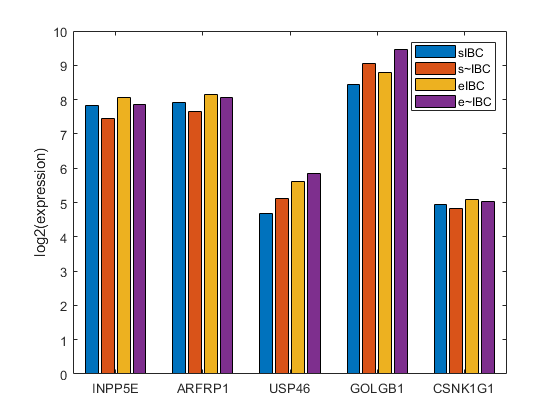

[~,Itop5]=sort(dpvals.double(:,1));
Itop5 = Itop5(1:5);
top5avg = zeros(5,4);
top5std = zeros(5,4);
for gi=1:4
	top5avg(:,gi) = mean(d.double(Itop5, Igroups==gi),2);
	top5std(:,gi) = std(d.double(Itop5, Igroups==gi),[],2);
end
%bmes_fig top5; clf
bar(top5avg);
ylabel('log2(expression)')
h=gca; h.XTickLabel=d.rownames(Itop5);
legend(groupnames);

%bmes_setniceylim;

## Plot the expression levels of top gene using boxplots

boxplot(d.double(Itop5(1),:)',Igroups');
% TODO: set xticks / ylabel.

pvalue is good to know, but we usually also want to know the fold changes (How different the average expression is between groups).

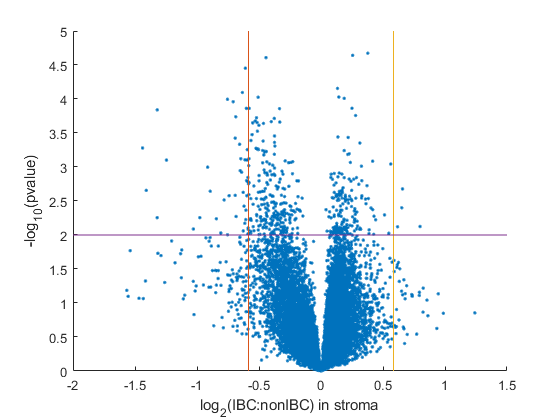

% Note that this GSE data is already log2-transformed. So, calculation of
% fold change should involve a subtraction, not a division!
%log2fc = log2( mean(d(:,Istroma_ibc),2) ./ mean(d(:, Istroma_nonibc),2) );
log2fc = mean(d(:,Istroma_ibc),2) - mean(d(:, Istroma_nonibc),2);
scatter(log2fc, -log10(dpvals(:,1)), '.');
xlabel('log_2(IBC:nonIBC) in stroma'), ylabel('-log_{10}(pvalue)');

%mark fc>=1.5 and pvalue<=0.01
hold on;
plot(log2([2/3 2/3]), ylim, log2([1.5 1.5]), ylim)
plot(xlim, -log10([.01 .01]))

Print the top 5 genes, now with fold change. log2fc is not easy to interpret, let's convert it to negative fold change. So, a negfc=2 will mean IBC is 2-fold compared to nonIBC and a negfc=-2 will mean IBC is half of nonIBC.

negfc = 2.^log2fc;
negfc(negfc<1) = - 1./negfc(negfc<1);

% Add the foldchange information to the dpvals object:
dpvals=[dpvals bioma.data.DataMatrix(negfc,'ColNames',{'negfc'})];
% Select the genes with pvalue<=0.01 and FC>=1.5.
I = dpvals(:,'p-values')<=0.01 & abs(dpvals(:,'negfc'))>=1.5;
dsigfc = dpvals(I,:);
dsigfc = dsigfc.sortrows('p-values');
fprintf('Found %d genes with pvalue<=0.01 and FC>=1.5. Showing top 5:\n',size(dsigfc,1));

Found 47 genes with pvalue<=0.01 and FC>=1.5. Showing top 5:


disp(dsigfc(1:5,:))

                       p-values      negfc  
    GOLGB1             3.5171e-05     -1.526
    TTC3 /// TTC3P1    8.0151e-05    -1.5519
    MAGED2             0.00010088    -1.6866
    DNAJB9             0.00010968    -1.6335
    DZIP3              0.00013738    -1.5177


Matlab has a mavolcanoplot() tool that helps you explore significantly different genes for different pvalue and fold change cutoffs.

mavolcanoplot(d.double(:,Istroma_ibc), d.double(:,Istroma_nonibc), dpvals.double(:,1),'Labels',d.rownames)

## Writing data into Excel File

Create a cell array containing the data that you want appear in an Excel sheet.

I=find(dpvals(:,1)<=0.01);
nsig=numel(I);
xlsdata = cell(nsig, 3); %each row will contain genesymbol,pvalue,negfc
for i=1:nsig
	gene=dpvals.rownames{I(i)};
	p=dpvals.double(I(i), 1);
	nfc=dpvals.double(I(i), 2);
	xlsdata(i,:) = {gene p nfc};
end

xlsdata=[ {'genesymbol' 'pvalue' 'negfc'}; xlsdata]; %add the header row.
xlswrite('stromaibc.xlsx',xlsdata,'siggenesIBC_nonIBC');



%-------------------------------------------------------------------------

## Data Analysis: Hierarchical Clustering

Let's cluster genes and samples using hierarchical clustering. Clustering can be very time consuming, so let's only do it for a subset of the genes.

% One idea is to only keep the genes that vary most across samples
% (ingoring sample groups.) This can be done using:
I=genevarfilter(d, 'Percentile',99); %remove 99% of genes
% Removing 99% is too aggressive. If your computing time and memory allow,
% use 90%.
d2 = d( I, :);

% Another option is to keep the genes that vary across sample groups. Since
% we already did differential expression analysis above, let's use the genes
% resulting from it. (Note that we only compared IBC vs. nonIBC in stroma;
% one would really need to repeat differential expression analysis for
% other pairs of groups of samples, and use the union of all significant
% genes).
Isig=dpvals(:,'p-values')<=0.05; %let's use 0.05 threshold to get some more genes.
d2 = d(Isig,:);
cg = clustergram(d2,'Standardize','Row');

## Data Analysis: "Flat" clustering

You can cluster genes (or samples) without a hierarchy. There are different methods for that. You can start off from a hierarchical clustering and "cut" the tree at a certain level to get a flat level of groupings.

% Let's create a distance matrix between pairs of genes.
% pdist() gives a vector (to save space). If you want the symmetric matrix,
% just pass the result through squareform().
genedist = pdist(d2,'spearman'); 

% linkage() hierarchically groups the genes. The result contains
% information about which two groups are combined at each branch.
tree = linkage(genedist,'average');

% visualize the tree, show only 20 nodes.
% Groups of genes will have a numerical id for labels.
%bmes_fig geneclust; clf
dendrogram(tree,20,'Labels',d2.rownames);
h=gca;
h.XTickLabelRotation=45;

let's now cut the tree to generate 6 clusters. The result is a membership vector, assigning each gene to one of the 6 clusters.

Iclust = cluster(tree, 'maxclust', 6);

% Let's plot each group of genes separately.
%bmes_fig geneclust; clf
for i=1:6
	subplot(2,3, i);
	plot( d2(Iclust==i, :)' );
end

The figure is too crowded. Let's show the average expression for the genes in each cluster.

d2avg=zeros(6,size(d2,2));
for i=1:6
	d2avg(i,:) = mean(d2(Iclust==i,:),1);
end
%bmes_fig geneclust; clf
clf; plot(d2avg');

end

% If this were a time-series experiment, plotting with x axis representing
% time would be informative. However, in this experiment, The x axis
% represents samples, whose ordering doesn't mean much.. Let's instead 
% show average values for different groups.
d2avgavg=zeros(6,4);
for i=1:6; for j=1:4
		d2avgavg(i,j) = mean(mean(d2(Iclust==i,Igroups==j)));
end; end
%bmes_fig geneclust; clf
bar(d2avgavg); legend(groupnames);
xlabel('gene clusters');
ylim([6 8]);
%bmes_setniceylim;

## Data-Analysis: k-means clustering

k-means is another method to generate groups of genes.

Iclust = kmeans(d2, 6, 'dist','corr');

% Once you have the Iclust membership values, you can again generate
% similar plots as above.
d2avgavg=zeros(6,4);
for i=1:6; for j=1:4
		d2avgavg(i,j) = mean(mean(d2(Iclust==i,Igroups==j)));
end; end
%bmes_fig geneclust; clf
bar(d2avgavg); legend(groupnames);
xlabel('gene clusters');
ylim([4 8]);
%bmes_setniceylim;

## Data Analysis: Principal Component Analysis (PCA)

Each gene is a multi-dimensional vector (as many dimensions as the number of samples). We often want to visualize genes in a lower (2D) space. Let's use PCA to reduce data dimensionality while preserving as much of the original information as possible.

[pc, reduced, pcvars] = pca(d2);

% reduced has as many columns as the original data. But the first column
% now contains the most information, the second column contains the second
% most, etc. Let's just use the first two columns to show genes on a
% figure.
%bmes_fig pca; clf
scatter(reduced(:,1), reduced(:,2));

We can combine the clustering and PCA and show the genes in different clusters with a different color.

%bmes_fig pca; clf
gscatter(reduced(:,1), reduced(:,2), Iclust);

% we can label the points using the text() function. Let's do that for the
% first 5 genes.
for i=1:5; text(reduced(i,1),reduced(i,2), d2.rownames{i}, 'FontWeight','bold', 'FontSize',13); end

% Whenever you show results of PCA, you should report the amount of
% variance captured by the reduced data.
pcvars = pcvars / sum(pcvars);
xlabel(sprintf('%%%.1f of variance', pcvars(1)*100));
ylabel(sprintf('%%%.1f of variance', pcvars(2)*100));



%-------------------------------------------------------------------------

## Data Analysis: Gene Set Enrichment

We have found the significantly different genes between two groups. But what do these genes do? Are there significant differences in biological functions between two groups? To answer these questions, we'll make use of the Gene Ontology terms, which annotate each gene to one or more Biological Processes, Cellular Components, and Molecular Functions.

gplgobio  = gpl.Data(:, strcmp(gpl.ColumnNames, 'Gene Ontology Biological Process'));
% The biological process of the first microarray probe:
gplgobio{1}

ans = '0001558 // regulation of cell growth // inferred from electronic annotation /// 0001952 // regulation of cell-matrix adhesion // inferred from electronic annotation /// 0006468 // protein phosphorylation // inferred from electronic annotation /// 0007155 // cell adhesion // traceable author statement /// 0007169 // transmembrane receptor protein tyrosine kinase signaling pathway // inferred from electronic annotation /// 0007565 // female pregnancy // inferred from electronic annotation /// 0007566 // embryo implantation // inferred from electronic annotation /// 0007595 // lactation // inferred from electronic annotation /// 0008285 // negative regulation of cell proliferation // inferred from electronic annotation /// 0010715 // regulation of extracellular matrix disassembly // inferred from mutant phenotype /// 0014909 // smooth muscle cell migration // inferred from mutant phenotype /// 0016310 // phosphorylation // inferred from electronic annotation /// 0018108 // peptidyl

The Gene Ontology terms are given as a list separated by '///'. Let's convert each into a cell array, to make programming with them easier.

for i=1:numel(gplgobio)
	%handle empty separately, b/c strsplit doesn't work as we want for empty strings.
	if isempty(gplgobio{i}); gplgobio{i}={};
	else gplgobio{i} = strsplit(gplgobio{i},' /// '); end
end

% Let's reduce amount of memory by keeping a master list of Biological
% Processes and have each probe have indices to that master list.
GOBIO = unique( [gplgobio{:}] );

% And use the "map" technique to search for each term in the GOBIO list.
map = containers.Map(GOBIO,1:numel(GOBIO));
for i=1:numel(gplgobio)
	for j=1:numel(gplgobio{i})
		gplgobio{i}{j} = map(gplgobio{i}{j});
	end
	gplgobio{i} = cell2mat(gplgobio{i});
end

Now each gplgobio is a numeric array.

gplgobio{1}

ans =          502         937        2722        4113        4181        4747        4754        4795        5065        6042        6595        7036        7312        8359       11533       11534       11537       12928       13127       14563       17378       17637       17941


To get the actual terms, use these numbers as indices to the GOBIO list.

GOBIO( gplgobio{1} )'

ans = 23×1 cell array
    {'0001558 // regulation of cell growth // inferred from electronic annotation'                                       }
    {'0001952 // regulation of cell-matrix adhesion // inferred from electronic annotation'                              }
    {'0006468 // protein phosphorylation // inferred from electronic annotation'                                         }
    {'0007155 // cell adhesion // traceable author statement'                                                            }
    {'0007169 // transmembrane receptor protein tyrosine kinase signaling pathway // inferred from electronic annotation'}
    {'0007565 // female pregnancy // inferred from electronic annotation'                                                }
    {'0007566 // embryo implantation // inferred from electronic annotation'                                             }
    {'0007595 // lactation // inferred from electronic annotation'                                                   

We have made the gplgobio more convenient to work with, but we really need to get the gobio information for the gse probes. We need to map take the GSE probes and search them in the GPL probes again. We have previously created the MAP_GSE_GPL, which we can use again.

gsegobio = cell(size(d,1),1); %any probe not found in gpl will remain an empty vector.
gsegobio(find(MAP_GSE_GPL)) = gplgobio(MAP_GSE_GPL(find(MAP_GSE_GPL)));

Now we can go through each GOBIO term and see if our list of significant genes is enriched for that term (ie. if that Biological Process is significantly different between the groups we are comparing). We only need to do this for the GOBIO terms that have at least one significant gene for it. If it has no significant genes for it at all, we already know that Biological Process is not affected, so no need to run a statistical test for it.

Find the terms that have at least one significant gene for it.

Isig=dpvals(:,'p-values')<=0.01;
dsig = d(Isig,:);
dpvalssig = dpvals(Isig,:);
gsegobiosig = gsegobio(Isig);
candidategobio = unique( [gsegobiosig{:}] );

Let's just analyze the first candidate GO Biological process.

gobioid = candidategobio(1);
GOBIO{ gobioid }

ans = '0000038 // very long-chain fatty acid metabolic process // inferred from direct assay'

## Hypergeometric Test

To calculate the significance of a Biological Process, we'll use the hypergeometric test. We need the following four numbers:

x: number of samples drawn, with the desired characteristic. K: number of items with the desired characteristic in the population N: number of samples drawn M: size of the population

% x: The number of significant genes that are in this term.
x = nnz([gsegobiosig{:}] == gobioid)

x = 1

K: Number of genes (significant or not) that are in this term.

K = nnz([gsegobio{:}] == gobioid)

K = 9

- N: Total number of significant genes. (ignore those with no GO term).

N = nnz( ~cellfun(@isempty,gsegobiosig) )

N = 399

gsegobio

gsegobio = 22283×1 cell array
    {[                                                                                                                                                                                                                                                                                                        502 937 2722 4113 4181 4747 4754 4795 5065 6042 6595 7036 7312 8359 11533 11534 11537 12928 13127 14563 17378 17637 17941]}
    {[                                                                                                                                                                                                                                                                                                                                                                         235 345 351 2251 2284 2307 2315 2334 2344 6878 6892 9358]}
    {[                                                                                                                

M: Total number of genes. (ignore those with no GO term).

M = nnz( ~cellfun(@isempty,gsegobio) )

M = 19017

Calculate and print the pvalue for this Biological Process.

pval = hygecdf(x,M,K,N,'upper');
fprintf('pvalue=%f for the GO Biological Process [%s]\n',pval,GOBIO{gobioid});

% We calculated the pvalue for only one of the candidate terms. You would
% of course want to calculate a pvalue for all candidate terms, apply FDR
% correction, and report only the most significant ones.